# World oil production

## Polynomial Interpolation

The total world oil production in millions of barrels per day is shown in the table that follows. Determine and plot the degree 9 polynomial through the data. Use it to estimate 2010 oil production. Does the Runge phenomenon occur in this example? In your opinion, is the interpolating polynomial a good model of the data? Explain.

year bbl/day (×10^6)

1994 67.052

1995 68.008

1996 69.803

1997 72.024

1998 73.400

1999 72.063

2000 74.669

2001 74.487

2002 74.065

2003 76.777

years=1994:2003

years =         1994        1995        1996        1997        1998        1999        2000        2001        2002        2003


bbl_day=[67.052, 68.008, 69.803, 72.024, 73.400, 72.063, 74.669, 74.487, 74.065, 76.777];

Lagrange interpolation - barycentric form

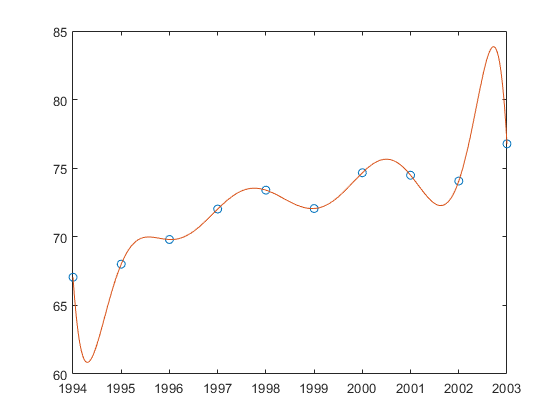

addpath('../interpdemo')
t=linspace(1994,2003,500);
zoil=baryLagrange(years, bbl_day, t);
plot(years,bbl_day,'o',t,zoil)

No, it exhibits larg oscilations on left and right subinterval

## Least squares

m=mean(years); sigma=std(years)

sigma = 3.0277

xy=(years-m)/sigma;
p=polyfit(xy, bbl_day,4)

p =     0.8422    0.5055   -2.5467    2.1270   73.3154


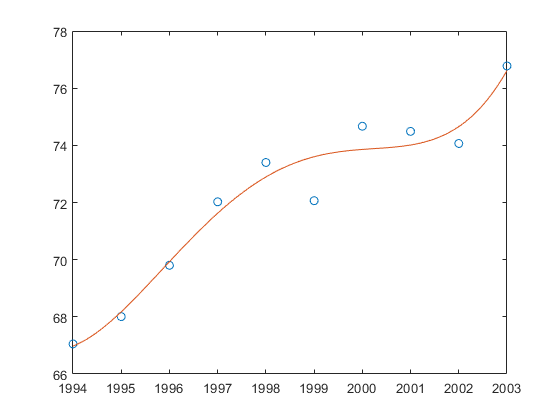

txy=(t-m)/sigma;
zoillsq=polyval(p,txy);
plot(years,bbl_day,'o',t,zoillsq)

## Spline Intrpolation

In a single plot, show the natural, not-a-knot, and parabolically terminated cubic splines through the world oil production data from previous Computer Problem.

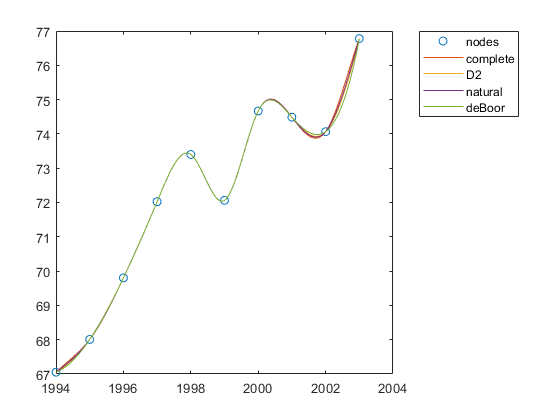

d1=diff(bbl_day); d1d=d1([1,end]);
d2=diff(d1)/2; d2d=d2([1,end]);
c1 = CubicSplinec(years,bbl_day,0,d1d);
c2 = CubicSplinec(years,bbl_day,1,d2d);
c3 = CubicSplinec(years,bbl_day,2);
c4 = CubicSplinec(years,bbl_day,3);
z1 = evalsplinec(years,c1,t);
z2 = evalsplinec(years,c2,t);
z3 = evalsplinec(years,c3,t);
z4 = evalsplinec(years,c4,t);
plot(years,bbl_day,'o',t,[z1';z2';z3';z4'])
legend('nodes','complete','D2','natural','deBoor','Location','bestoutside');

## Piecewise Hermite

zz=pchip(years,bbl_day,t)

zz =    67.0520   67.0619   67.0721   67.0826   67.0935   67.1047   67.1163   67.1282   67.1404   67.1530   67.1658   67.1790   67.1925   67.2062   67.2203   67.2347   67.2493   67.2643   67.2795   67.2950   67.3108   67.3268   67.3431   67.3596   67.3764   67.3935   67.4108   67.4283   67.4461   67.4641   67.4823   67.5007   67.5194   67.5383   67.5574   67.5766   67.5961   67.6158   67.6357   67.6557   67.6759   67.6964   67.7169   67.7377   67.7586   67.7797   67.8009   67.8222   67.8438   67.8654


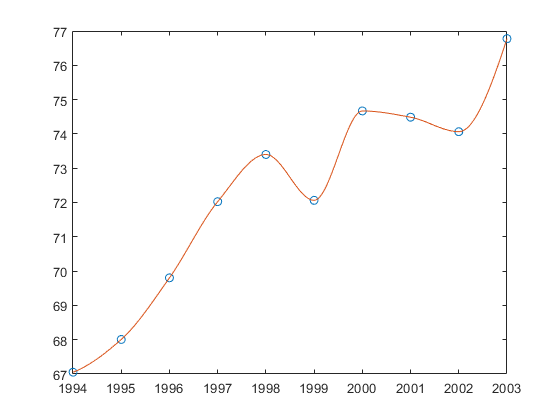

plot(years,bbl_day,'o',t,zz)